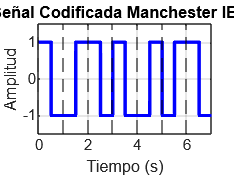

clc; clear; close all;

% Definir la cadena de bits de entrada
bits = [1 0 1 1 0 0 1]; % Puedes cambiar esta secuencia

% Parámetros de la señal
fs = 1000; % Frecuencia de muestreo en Hz
bit_duracion = 1; % Duración de cada bit en segundos
t = 0:1/fs:length(bits)*bit_duracion - 1/fs; % Vector de tiempo

% Generar la señal Manchester IEEE
manchester_ieee = zeros(1, length(t));

for i = 1:length(bits)
    idx = (i-1)*fs*bit_duracion + 1 : i*fs*bit_duracion; % Índices del tiempo para cada bit
    if bits(i) == 0
        manchester_ieee(idx(1:floor(end/2))) = -1; % Primera mitad del bit: -1 (bajo)
        manchester_ieee(idx(floor(end/2)+1:end)) = 1; % Segunda mitad del bit: +1 (alto)
    else
        manchester_ieee(idx(1:floor(end/2))) = 1; % Primera mitad del bit: +1 (alto)
        manchester_ieee(idx(floor(end/2)+1:end)) = -1; % Segunda mitad del bit: -1 (bajo)
    end
end

% Graficar la señal codificada
figure;
plot(t, manchester_ieee, 'b', 'LineWidth', 2);
ylim([-1.5, 1.5]);
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Señal Codificada Manchester IEEE');
grid on;

% Agregar líneas verticales para separar los bits
hold on;
for i = 1:length(bits)
    xline((i-1)*bit_duracion, '--k');
end
hold off;